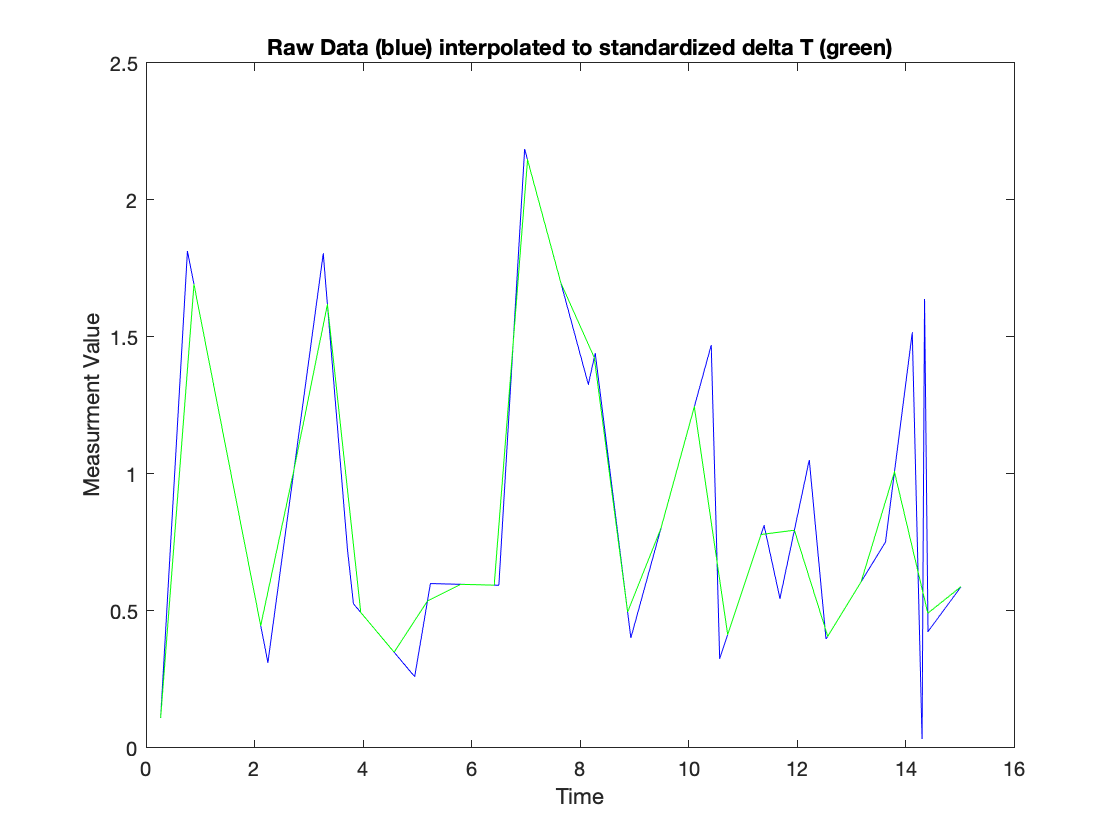

clearvars

%{
Parent Version: Interpolation_20211005_v3

Simple Linear Interpolation: cleaned up and make it into 
a function usable with real data. (The program figures out the average time delta, 
resets the timescale to this standard, then performs a simple linear interpolation 
of the measurment values)

%}

% --Random Simulated Observational Data--
n = 25;
T = zeros(1,n);
T(1) = abs( random('Normal',0,1) );
for l = 2:n
    T(l) = T(l-1) + abs ( random('normal',0,1) );
end
M = abs( random('Normal',0,1,1,n) );


% --Input Actual Data--
%T = [1 2 5 6 7 8 10 11 12 15 18 29 20 21 22 23 25 28 29 30 ]'  
%M = random('Normal',0,20) ;                                      
                                                



%--Call the Linear Interpolation Function--

[Tnew,Mnew] = Interp_Lin(T,M);

function [Tnew,Mnew] = Interp_Lin(T,M)

% --Sum all of the time differences between measurements--
n = numel(T);
sum = 0;
for l = 1:n-1
    
    sum = sum + abs(T(l+1) - T(l));
end

% -- find averaged time scale--
avg_dT = sum / (n-1);
Tnew = T(1):avg_dT:T(n);

%--Calculate Mnew values--
m = numel(Tnew);
Mnew = zeros(1,m);

Mnew(1) = M(1);
Mnew(m) = M(n);

for l = 2:m-1
    for k = 1:n  
       if T(k) <= Tnew(l)
           if Tnew(l) <= T(k+1)
               Mnew(l) =   ( M(k+1) - M(k) ) ./ ( T(k+1) - T(k) ) .* ( Tnew(l)-T(k) ) + M(k) ;  %eq for a line. i.e. y = mx + b
           end
       end
    end
end




plot(T,M,'b',Tnew,Mnew,'g')
title('Raw Data (blue) interpolated to standardized delta T (green)')
xlabel('Time')
ylabel('Measurment Value')
end





